# Team 45 Forrest Fire UAV

## **Background:**

Heat and drought in the western United States has resulted in greater numbers and more devastating forest fires.  Fighting forest fires requires an experienced ground crew and often heavy-lift operations in an extreme environment coordinated through observations and communications.  A field-ready UAV possessing visual and sensor-based observations, communications, reactive response and lift/ballast capabilities can contribute to operational support of the fire crew and its safety.

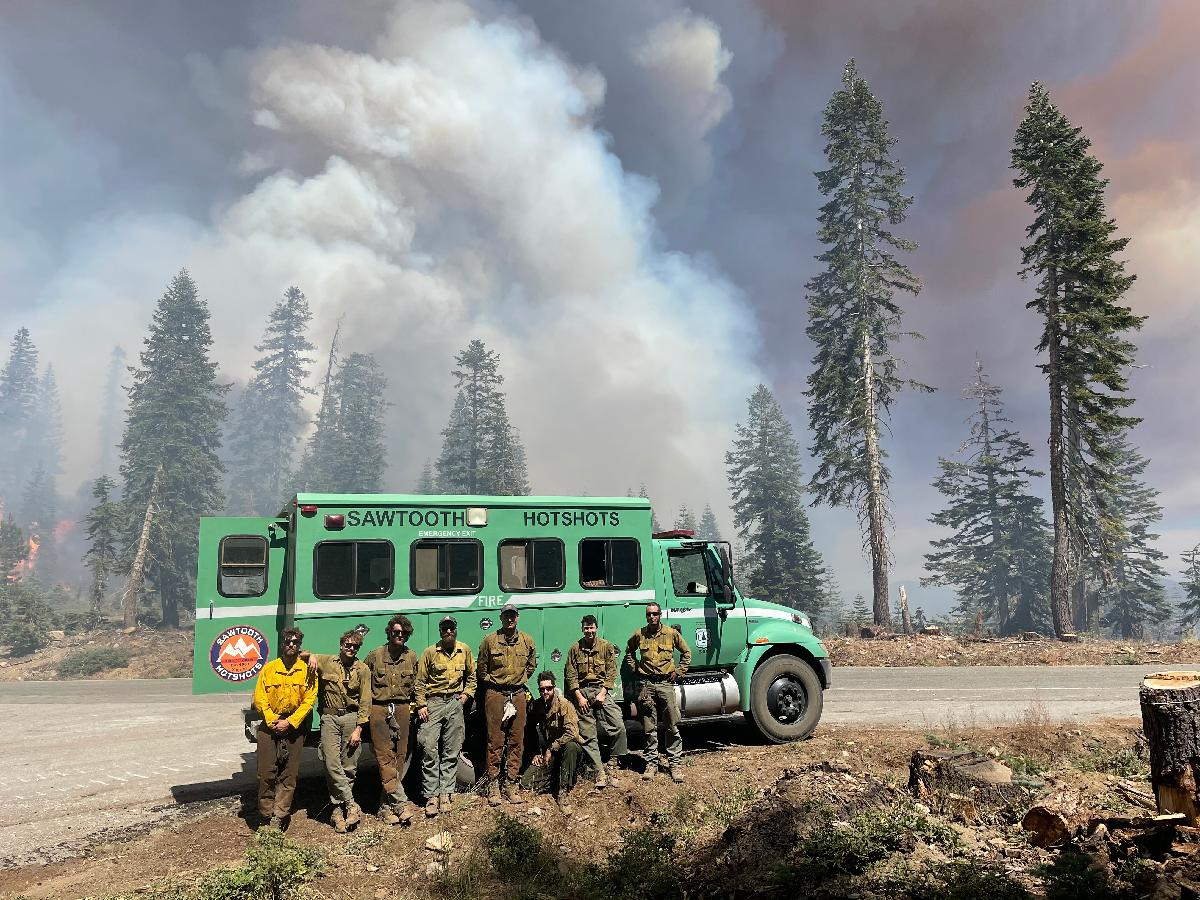

## **Project Description:**

Year 1 of the *Forest Fire UAV Platform *project is to design/develop a UAV platform (airframe, powerplant and propulsion) for a field-ready UAV developed to support crews fighting forest fires.  The UAV requires light air-lift capability, high heat, weather and damage tolerance, it must be stable in higher winds and altitudes.  The UAV platform needs to be simple, field-serviceable and travel with the crew deployed from their truck.  A test subsystem, including safe test fixtures, test cell and data acquisition, will be developed to qualify the structural airframe, powerplant and propulsion subsystems.

### Major Design Tasks:

Specifically, the *Forest Fire UAV Platform* project is to design, develop, build  and test the UAV platform.  The are four (4) major tasks in the year 1 project:

- Custom Airframe Structure Design:  Trade-off studies for concept selection between helicopters, quadcopters, hexacopters, octocopters etc . . . will be conducted.   Light-weighting of the airframe is important while "best" supporting damage tolerance, deformation, stiffness and load requirements.  Stable, light air-lift of tool, instrumentation, rescue, medical payloads is required.  Transport by truck from site-to-site by highway and rough terrain as well as field serviceability is required.

- Power Plant Design:  The primary design task for the power plant is to configure, size and select battery and/or hydrogen fuel cell subsystems, including storage.  Hybrid designs may be required.  Fast, robust field refueling/recharging is desired.

- Propulsion Subsystem Design:  Configuration and sizing of motors and propellers to maximize the hover operational mode flight time with a light air-lift payload.  Electric motors will likely be the *prime mover* selected for power and weight.  Trade-off studies for propulsion could include shrouded contra-rotating propellers.  Flight stability with payload in hot wind gusts and at higher elevation is required.

- Test Fixture/Cell Design: The design, development and fabrication of test fixtures and test cell is required to determine operational design parameters leading to qualifying the design.  Test fixtures and test cell support data acquisition for design cases such as:

- What structural loads are developed in air-lift and observation modes, how do wind gusts change structural loading?  Is the airframe damage tolerant, what is the expected life of the airframe?

- What is the power vs. time of the power plant?  How much heat is generated under load in the power plant?  Is the power output sensitive to forest fire heat?  How long can the air-lift be maintained?  What is the power budget for the platform, is power available for sensors, communications and controllers?

- Does the powertrain generate the required lift? How do the flight characteristics change vs. speed, power and weight?   How many lifting elements are needed for fault tolerance?  How stable is the platform?

- *Constrained flight* is performed in the "test cell" to **safely** conduct testing, flight qualification and demonstration.  *Constrained flight* is limited to vertical hover to demonstrate light air-lift capability and hover flight-time duration.

**Note:**  Outfitting the *Forest Fire UAV platform* with sensors for observations, communications, controls for piloted and/or autonomous free-flight is beyond the scope of the year 1 project.

### **Desired Student Skillset:**

Project skills include CAD and model-based design (MATLAB/Python) to support selection and initial design of the UAV airframe structure, power plant and propulsion subsystems.  Light-weighting will be an important element of the airframe design which includes material characterization/selection.  Interest is sensors and data acquisition for test, system integration and qualification is desired.  FEA and CFD will be used to support refined design analysis and optimization.  Drone experience is helpful even though UAV free flight is not within the scope of the year 1 project.

### **Special Considerations:**

No special requirement for student status.

## Team Leadership Responsibilities:

- Team Leader:  James Drosdick

- Aero Structure:  Roshen Arun

- Propulsion:  Jake Giacchetto

- Power:  Reda Morchid

- CAD:  Renee Van Dyke

- MATLAB Design Model:  Kieun Nam

- Testing:  Evan Grace

- Fabrication:  Livingstone Bond

## Team Member Responsibilities:

- Aero Structure:  Roshen Arun (lead), Renee Van Dyke, Livingstone Bond, Kieun Nam

- Propulsion:  Jake Giacchetto (lead), James Drosdick, Evan Grace, Reda Morchid

- Power:  Reda Morchid (lead), Kieun Nam, James Drosdick

- Test:  Evan Grace (lead),

- Fabrication:  Livingstone Bond (lead)

## HouseKeeping

clc; clear; close;

## Initial Motor Analysis 10/22/22

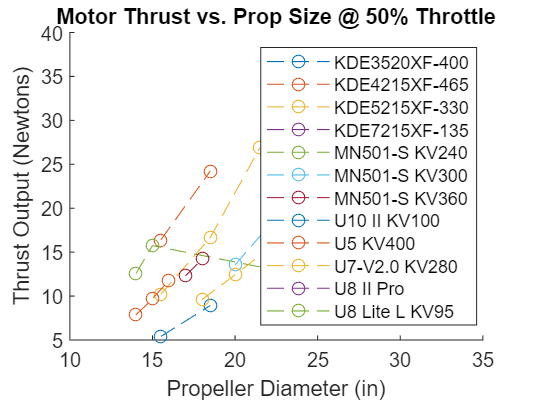

% Thrust Threshold Estimation
% Set-up 
oldfolder = cd('CSVs');
cd('Motor Data - Motor Processing')
Payload = 35; % lb
BatteryW = 3; % kg 
MotorW = 250; % g
WeightFS = 1.2; % Dimensionless 

% Conversion
Payload = Payload*0.453592; % lb -> kg conversion
MotorW = MotorW/1000; % g -> kg conversion

%% DownForce
TotalDownForce = (Payload+8*MotorW+BatteryW)*9.8*1.2;
MAXThrustEst = TotalDownForce*2 ;
Thrust_Threshold = MAXThrustEst/8;
% Load Data
Motor_Names = ["KDE3520XF-400","KDE4215XF-465","KDE5215XF-330","KDE7215XF-135" ...
    "MN501-S KV240","MN501-S KV300","MN501-S KV360","U10 II KV100","U5 KV400","U7-V2.0 KV280","U8 II Pro","U8 Lite L KV95"];
%Motor Thrust vs. Prop Size @ 50% Throttle
for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    PropD = Motor_Matrix(:,1);
    Thrust = Motor_Matrix(:,2)*0.009807; %convert Grams to Newtons
    figure(1)
    hold on
    title('Motor Thrust vs. Prop Size @ 50% Throttle')
    xlabel('Propeller Diameter (in)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

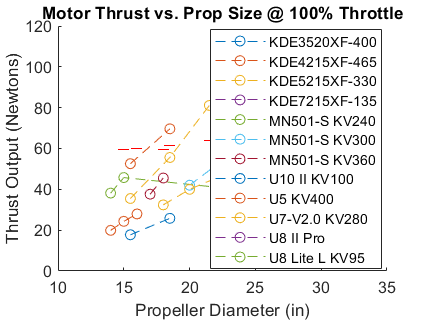

%Motor Thrust vs. Prop Size @ 100% Throttle
for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(2)
    Thrust = Motor_Matrix(:,3)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,1);
    [Max_thrust(n),MaxT_Index(n)] = max(Thrust);
    propD_all(n) = Motor_Matrix(MaxT_Index(n),1);
    
    % Thrust Threshold Calc
    Payload = 35*0.453592;              %kilograms
    Est_Battery_W = 3;                  %kilograms
    MotorW = Motor_Matrix(end,9)/1000;  %kilograms
    TotalDownForce = (Payload+8*MotorW+Est_Battery_W)*9.8*1.2; %Newtons
    MAXThrustEst = TotalDownForce*2; 
    Thrust_Threshold(n) = MAXThrustEst/8;                    %Newtons
    

    if (Max_thrust(n) > Thrust_Threshold(n))
        Acceptable_Motors(n) = Motor_Names(n);
    end

    hold on
    title('Motor Thrust vs. Prop Size @ 100% Throttle')
    xlabel('Propeller Diameter (in)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
plot(propD_all,Thrust_Threshold, 'r_')
legend(Motor_Names,'Location',"best")

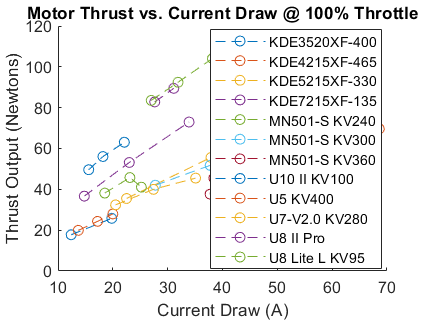

Acceptable_Motors = rmmissing(Acceptable_Motors);
%current draw vs thrust
for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(3)
    Thrust = Motor_Matrix(:,3)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,5);
    hold on
    title('Motor Thrust vs. Current Draw @ 100% Throttle')
    xlabel('Current Draw (A)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

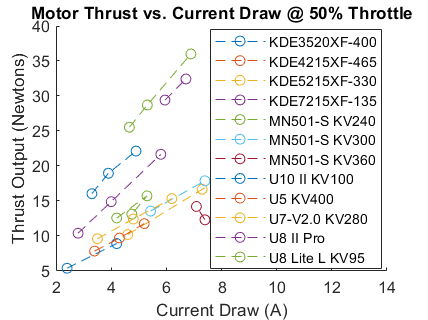


for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(4)
    Thrust = Motor_Matrix(:,2)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,4);
    hold on
    title('Motor Thrust vs. Current Draw @ 50% Throttle')
    xlabel('Current Draw (A)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

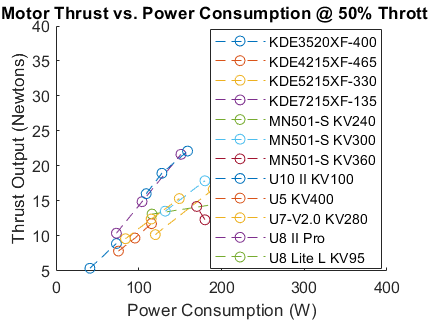

% Thrust Vs. Power
for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(5)
    Thrust = Motor_Matrix(:,2)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,6);
    hold on
    title('Motor Thrust vs. Power Consumption @ 50% Throttle')
    xlabel('Power Consumption (W)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

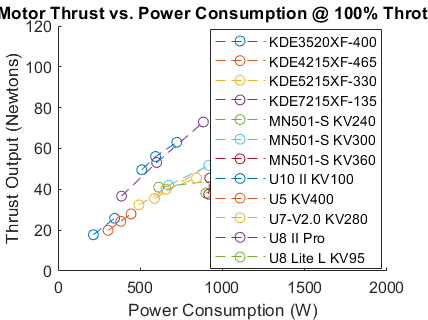


for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(6)
    Thrust = Motor_Matrix(:,3)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,7);
    hold on
    title('Motor Thrust vs. Power Consumption @ 100% Throttle')
    xlabel('Power Consumption (W)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")
hold off

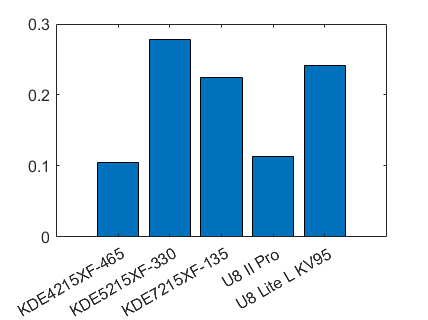

% Thrust to weight ratio
for n = 1:length(Acceptable_Motors)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    Thrust = Motor_Matrix(end,3)*0.009807; % convert grams to Newtons
    T2W(n) = Thrust / Motor_Matrix(end,9);
end
figure(7)
title('Max Thrust to Weight Ratio Per Motor')
grid on
bar(T2W)
xticklabels(Acceptable_Motors)

cd(oldfolder)


## Acceptable Motors and Batteries

% cd into relevent folder
    oldfolder = cd('CSVs');

### Motors and Props

data = readtable('Acceptable_Motors3.csv', "Delimiter", ',','Range','A3:BS12');
    table(data.Var1, data.Var10, data.Var11,'VariableNames',["Motor Name","Prop Diameter [in]","Prop Pitch [in]"])

ans = 10×3 table
        Motor Name        Prop Diameter [in]    Prop Pitch [in]
    __________________    __________________    _______________

    {'KDE4215XF-465' }           15.5                 5.3      
    {'KDE4215XF-465' }           18.5                 6.3      
    {'KDE5215XF-330' }           18.5                 5.3      
    {'KDE5215XF-330' }           21.5                 7.3      
    {'KDE7215XF-135' }           30.5                 9.7      
    {'U8 II Pro'     }             27                 8.8      
    {'U8 II Pro'     }             28                 9.2      
    {'U8 Lite L KV95'}             29                 9.5      
    {'U8 Lite L KV95'}             30                10.5      
    {'U8 Lite L KV95'}             32                  11      


### Batteries

readtable('Battery Data 2.csv', "Delimiter", ',','Range','A2:A17')

ans = 15×1 table
                       BatteryName                    
    __________________________________________________

    {'DIAMOND 6S 22000mAh solid-state li-ion battery'}
    {'DIAMOND 6S 27000mAh solid-state li-ion battery'}
    {'DIAMOND 6S 30000mAh solid-state li-ion battery'}
    {'DIAMOND 6S 23000mAh solid-state li-ion battery'}
    {'Tattu 32000mAh 22.8V 10C 6S1P'                 }
    {'Tattu 40000mAh 22.8V 10C 6S1P'                 }
    {'Tattu 10000mAh 22.2V 25C Lipo Battery'         }
    {'NAGA Series Battery'                           }
    {'Tattu 30000mAh 22.2V 25C Lipo Battery Pack'    }
    {'T-Drones Ares 6s 30000mAh Li-ion Rechargable'  }
    {'Foxtech 6S 12500mAh Li-ion Battery'            }
    {'Li-ion 10000 11S2P 39.6v Battery Pack'         }
    {'Tattu 23000 mAh 22.8V LiHv Pouch Cell'         }
    {'FoxTech 6S 22000 mAh Lipo Battery'             }
    {'Tattu 22.2V 22000 mAh Lipo Battery'            }


% cd out to main
    cd(oldfolder)

## Optimization Loop 

%% Optimization Script
% housekeeping
clc; clear; close all;
% initialize
Passed_configs = cell(1,8);
Payload = 25; %lbs
t = 0;
Distance = 16; %distance in miles
% loop
for i = 9:10
    D = James_MotorCombo(i);
    for j = 6
        B = BatteryInfo(j);
        for k = 1
            % checks
            [CurrentCheck, ThrustCheck, TDF] = Current_thrust_Check(D,B,Payload,k);
            % Tracking 
            if (CurrentCheck == 1 && ThrustCheck == 1)
                % Run the mission sim
                [Mission_Check, BCR, BCRP, Mission_Time] = MissionSim(D, B, Distance, TDF);
                if (Mission_Check == 1)
                    t = t+1;
                    PC(t,:) = {D.Motor_Name D.PropD B.Battery_Name k BCR BCRP Mission_Time Payload};
                end
            end
        end 
    end
end

Error using Team_45_FFUAV_Concept_Design>MissionSim
Too many output arguments.

%% find best run
format shortG
T = cell2table(PC);
T.Properties.VariableNames(1:8) = {'Motor','Prop Diameter (in)','Battery','# of Bats','Battery Remaining (mAh)','Battery Remaining (%)','Mission Time (min)','Payload (lbs)'};
disp(T)
% find best run
[BCRP,I] = max(cell2mat(PC(1:end,6)));
best = PC(I,:);
best_percent = num2str(BCRP) + "%";
format shortG
fprintf('Best run configuration is \n[')
fprintf('%s, ',best{1,1})
fprintf('%g, ',best{1,2})
fprintf('%s, ',best{1,3})
for i = 4:5
    fprintf('%g, ',best{1,i})
end
fprintf('%s, ',best_percent)
fprintf('%g, ',best{1,7})
fprintf('%g]\nwith %s Battery Remaining\n', best{1,end},best_percent)


## Objective Function Inputs

% Motor Prop combo
combonumber = 7; %Input Motor + Prop combination Number Variable
BatNumber = 2;   %Input Battery Number;
Payload = 25; % lbs
D = James_MotorCombo(combonumber);
B = BatteryInfo(BatNumber);
NB = 2;          % Number of Batteries

## Checks 

[CurrentCheck , Thrust_Check, TDF] = Current_thrust_Check(D,B,Payload,NB)

## MIssion Sim - 

function [Check,BCR,BCRP] = MissionSim(D,B,Distance,TDF)
%UNTITLED2 Summary of this function goes here
%   Detailed explanation goes here
%% Load Battery Capacity  BCR = Battery Capacity Remaining
BCR =  str2double(B.Battery_Cap_mAH);
%% Takeoff ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Load in Constants
F_Height = 100; % meters  --- Cruising Altitude
Takeoff_s = 20 * 1000/3600; % m/s --- Takeoff Speed
Takeoff_As = 3 * 0.092903; % m^2 --- Takeoff Surface Area *Var
P_row = 1.205; % kg/m^2 -- Air density
C_d = 1.2; % Coefficient of Drag *double check* 
% Calc Forces
Takeoff_Drag = 0.5*P_row*(Takeoff_s^2)*C_d*Takeoff_As; 
Takeoff_Est_t = F_Height/Takeoff_s; % in seconds
Takeoff_Total_DF = TDF + Takeoff_Drag;
% Determine Thrust and Current Needed for lift (approximately equilibrium)
[thrust_indx, ~] = ThrustGivenF_WIP(D, Takeoff_Total_DF);
Battery_Cap_Discharge = 0.8; 
Takeoff_Current_Draw = 8*D.Current_A(thrust_indx, 2);
Takeoff_Capacity_Usage_mAh = (Takeoff_Est_t / 3600) * (Takeoff_Current_Draw*1000) / Battery_Cap_Discharge;  
%% calculate battery remaining
BCR = BCR - Takeoff_Capacity_Usage_mAh;

%% Flight * probably needs to be its own function later
%% load constants
Distance = Distance*1609.34;  % miles --> meters
% Note: Cruising_s could be pulled from structures stuct
Cruising_s = 40 * 1000/3600; % m/s --- Cruising Speed

Cruising_As = 2; % ft^2 --- Takeoff Surface Area
Cruising_As = Cruising_As*0.092903; % m^2

P_row = 1.205; % kg/m^2 -- Air density
C_d = 1.2; % Coefficient of Drag *double check* 

Cruising_Drag = 0.5*P_row*(Cruising_s^2)*C_d*Cruising_As  ;
syms Ft t1; 
eqn1 = Ft*cosd(t1) == TDF;
eqn2 = Ft*sind(t1) == Cruising_Drag;
S = solve([eqn1, eqn2], [Ft,t1], "Real",true);
Thrust_Est_Cruise = double(S.Ft(1,1)); 
Angle_Est_Cruise = double(S.t1(1,1));

Cruising_Est_t = (Distance/Cruising_s)/60; % in minutes

[thrust_indx2, ~] = ThrustGivenF_WIP(D, Thrust_Est_Cruise) ;


Flight_Current_Draw = 8*D.Current_A(thrust_indx2, 2);
Flight_Capacity_Usage_mAh = (((Cruising_Est_t/60)*Flight_Current_Draw*1000)/Battery_Cap_Discharge); % mAh
%% calculate battery remaining
BCR = BCR - Flight_Capacity_Usage_mAh;
BCRP = BCR / str2double(B.Battery_Cap_mAH) * 100;
%% Hover --------------------------------------------------------------

%% Landing -------------------------------------------------------------
%% Check that there is Battery remaining
    if (BCRP > 10) % Check if mission is completed with more than 10% battery remaining
        Check = true;  %pass
    else
        Check = false; %fail
    end


end
